# **The influence of generation function**

The physical scenario is shown below: an x - or y-polarized plane wave is scattered by a dielectric/metallic Janus particle in free space. The axis of symmetry of the Janus particle coincides with the wave vector of plane wave.

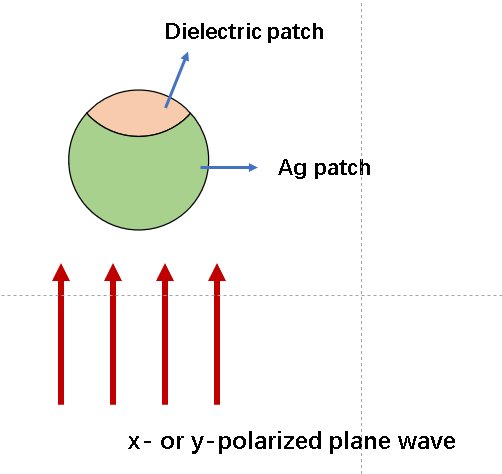

According to the symmetry, we predict that the scattering cross section of the particle is independent of the polarization mode of the incident light. Unfortunately, however, I find that the calculation results of the scattering cross section are directly related to the functions generating the Janus particle.

op = bemoptions( 'sim', 'ret', 'interp', 'curve');
epstab = {epsconst(1), epstable('Ag.csv'), epsconst(5)};

% --------------------------- particle class ------------------------
diameter = 100;
% silver nanoparticle with a diameter of 100 nm.
p1 = comparticle( epstab, { trisphere( 144, diameter ) }, [ 2, 1 ], 1, op );
% dielectric nanoparticle with a diameter of 100 nm.
p2 = comparticle( epstab, { trisphere( 144, diameter ) }, [ 3, 1 ], 1, op );
% janus particle generated with a diameter of 100 nm by trisphere function
inout = [2,1; 3,2; 3,1];  
p3 = comparticle( epstab, janus_trisphere(pi/3, diameter, 512, 1:3), ...
    inout, [1, -2], [2, 3], op);

trisphere: loading sphere529 from trisphere.mat


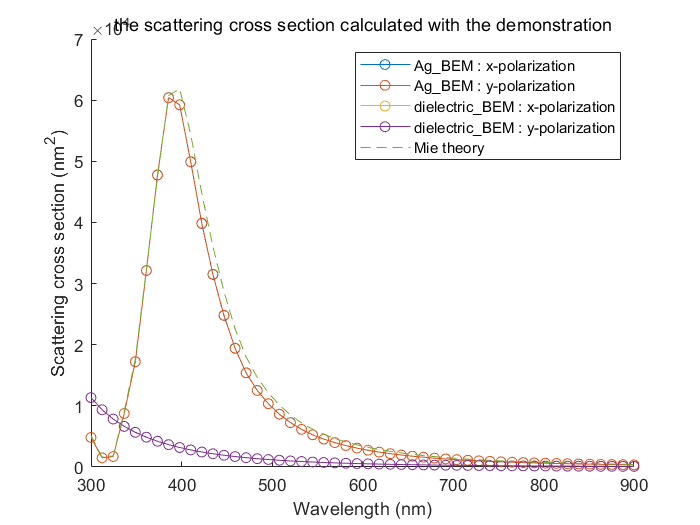

% janus particle generated with a diameter of 100 nm by trispheresegment function
p4 = comparticle( epstab, janus_trispheresegment(pi/3, diameter, 512, 1:3, 0), ...
    inout, [1, -2], [2, 3], op);
% p4 = comparticle( epstab, janus_trispheresegment(pi/3, diameter, 512, 1:2, 0), ...
%     [2,1;1,2], [1, -2], op);
p3 = rot(p3, -90, [1 0 0]);
p4 = rot(p4, -90, [1 0 0]);
% ------------------------- solver ---------------------------
bem1 = bemsolver( p1, op );
bem2 = bemsolver( p2, op );
bem3 = bemsolver( p3, op );
bem4 = bemsolver( p4, op );

% ----------------------- calculation -----------------------
% both x- and y-polarized plane wave are under consideration
exc = planewave( [ 1, 0, 0; 0, 1, 0 ], [ 0, 0, 1; 0, 0, 1 ], op );
enei = linspace( 300, 900, 50 );
sca1 = zeros( length( enei ), 2 );
sca2 = sca1; sca3 = sca1; sca4 = sca1;

multiWaitbar( 'BEM solver', 0, 'Color', 'g', 'CanCancel', 'on' );
for ien = 1 : length( enei )
    sig1 = bem1 \ exc( p1, enei( ien ) );
    sig2 = bem2 \ exc( p2, enei( ien ) );
    sig3 = bem3 \ exc( p3, enei( ien ) );
    sig4 = bem4 \ exc( p4, enei( ien ) );
    sca1( ien, : ) = exc.sca( sig1 );
    sca2( ien, : ) = exc.sca( sig2 );
    sca3( ien, : ) = exc.sca( sig3 );
    sca4( ien, : ) = exc.sca( sig4 );
    multiWaitbar( 'BEM solver', ien / numel( enei ) );
end
multiWaitbar( 'CloseAll' );
mie = miesolver( epstab{ 2 }, epstab{ 1 }, diameter, op );


% ---------------------- plot the scattering cross section-----------------------
figure; hold on
plot( enei, sca1, 'o-'  );  
plot( enei, sca2, 'o-'  );  
plot( enei, mie.sca( enei ), '--' );  
xlabel( 'Wavelength (nm)' );
ylabel( 'Scattering cross section (nm^2)' );
legend( 'Ag\_BEM : x-polarization', 'Ag\_BEM : y-polarization', ...
    'dielectric\_BEM : x-polarization', 'dielectric\_BEM : y-polarization', ...
    'Mie theory');
title('the scattering cross section calculated with the demonstration')

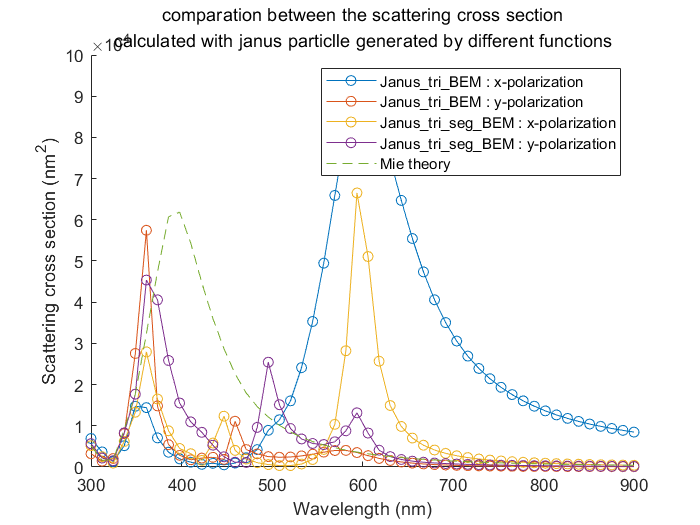

figure; hold on
plot( enei, sca3, 'o-'  );  
plot( enei, sca4, 'o-'  );  
plot( enei, mie.sca( enei ), '--' );  
xlabel( 'Wavelength (nm)' );
ylabel( 'Scattering cross section (nm^2)' );
legend( 'Janus\_tri\_BEM : x-polarization', 'Janus\_tri\_BEM : y-polarization', ...
    'Janus\_tri\_seg\_BEM : x-polarization', 'Janus\_tri\_seg\_BEM : y-polarization', ...
    'Mie theory');
title({'comparation between the scattering cross section'; ...
'calculated with janus particlle generated by different functions'});

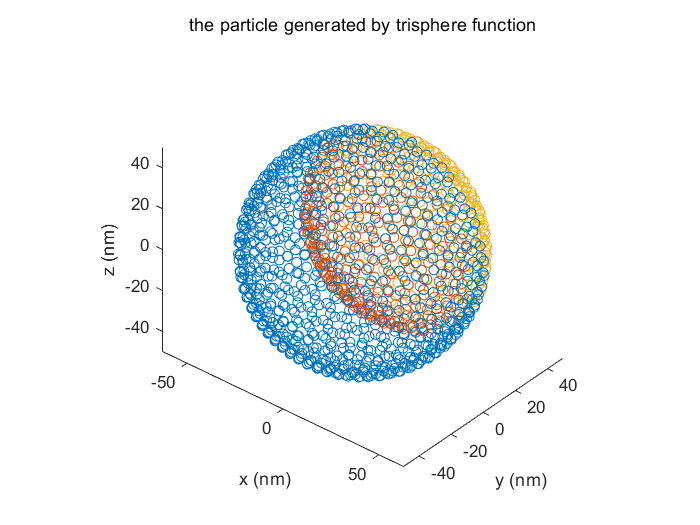

% ----------------------- plot the particles ------------------
plot_particle(p3); view(40,35)
title('the particle generated by trisphere function')
axis on; xlabel('x (nm)'); ylabel('y (nm)'); zlabel('z (nm)');

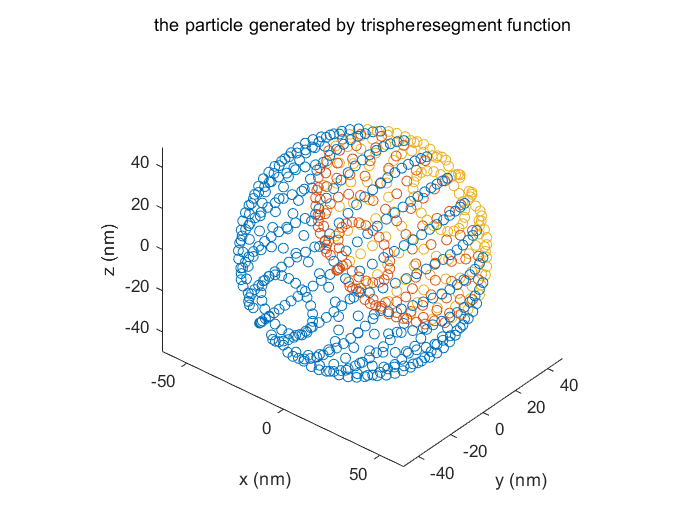

plot_particle(p4); view(40,35)
title('the particle generated by trispheresegment function')
axis on; xlabel('x (nm)'); ylabel('y (nm)'); zlabel('z (nm)');

# **Analysis**

It can be seen that for Janus particle obtained by trisphere function, the scattering cross section is polarization-dependent which's not physical.  

I think this is because the particle surfaces obtained by trisphere function is quasi-symmetric.  The edges of the particle surfaces, which generated by trisphere function, were serrated, just as shown in the figure below.

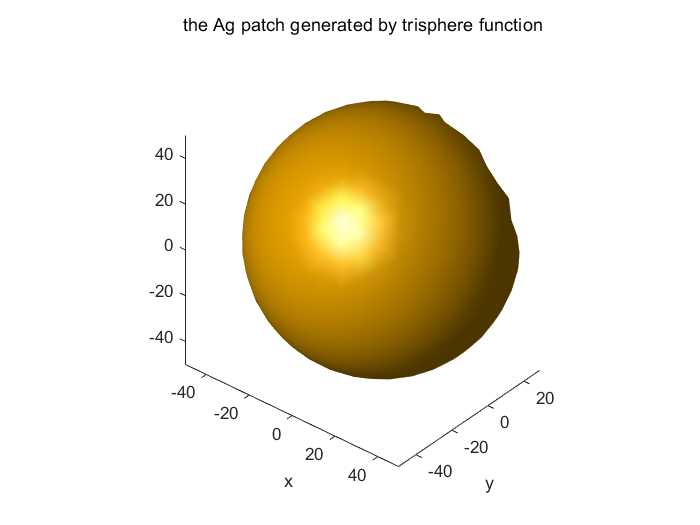

figure; plot(p3.p{1}); view(40,35)
axis equal; xlabel('x'); ylabel('y'); axis on
title('the Ag patch generated by trisphere function')

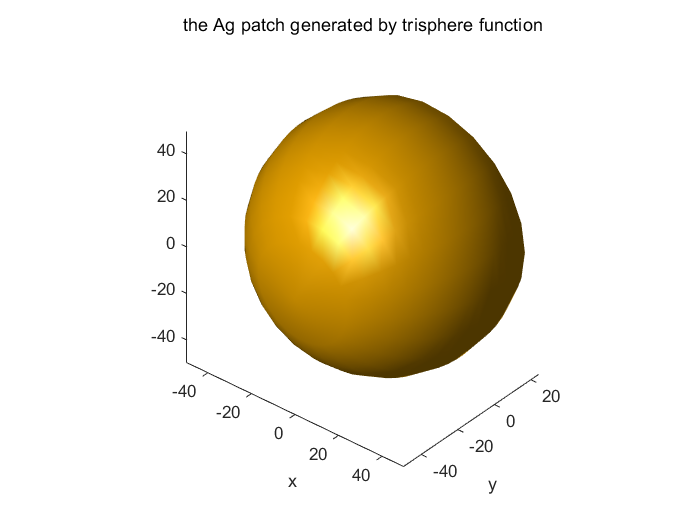

figure; plot(p4.p{1}); view(40,35)
axis equal; xlabel('x'); ylabel('y'); axis on
title('the Ag patch generated by trisphere function')

# **The trispheresegment function is not a panacea**

Although the result based on trispheresegment is expected, I don't know if it is correct due to my limited knowledge of physics. Even if this method is correct, when I want to calculate the scattering of a more complex particle, as shown below, there is no guarantee that the edge of the particle surface will be smooth. As mentioned before, this will cause serious computational errors.

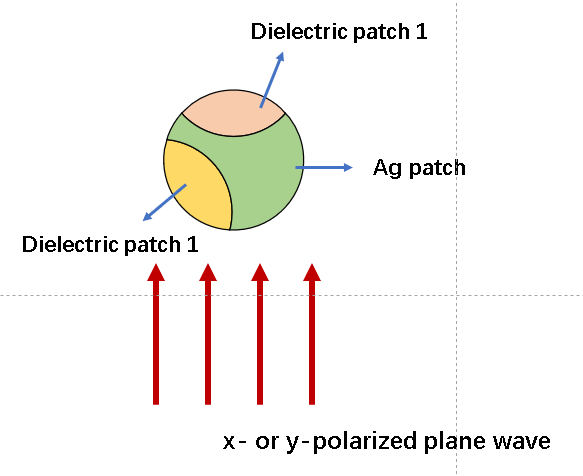

Could you please teach me a more general method of particle generation to deal with the scattering problem of such complex particles?

function p = janus_trisphere(theta_span, d, num, particle_ind)
% generating a janus particle with the trisphere function.
% 
% input:
%   theta_span: a parameter to determine the volume of the dielectric patch
%   d: the diameter of the nanoparticle
%   num: a number to determine the mesh density
%   particle_ind: a vector to determine which patches are choosed

    p0 = trisphere(num, d);
    [p_outer, p_Ag] = select(p0, 'sphfun', @(phi, theta, r) theta < theta_span);
    p_inner = p_outer.flip(3);      
    p_inner = p_inner.shift([0, 0, min(p_outer.verts(:,3))-max(p_inner.verts(:,3))-1e-3]);
    p = {p_Ag, p_inner, p_outer};
    p = p(particle_ind);
end

function p = janus_trispheresegment(theta_span, d, num, particle_ind, rotate_angle)
% generating a janus particle with the trispheresegment function.
% 
% input:
%   theta_span: a parameter to determine the volume of the dielectric patch
%   d: the diameter of the nanoparticle
%   num: a number to determine the mesh density
%   particle_ind: a vector to determine which patches are choosed
%   rotate_angle: a parameter to rotate the p0 particle to make a serrated
%                 edge

    dphi = 2*pi/round(sqrt(num));
    dcos_theta = 2/round(sqrt(num));
    theta = acos((1:-dcos_theta:-1));
    phi = 0:dphi:2*pi;
    
    p0 = trispheresegment(phi, theta, d);
    p0 = p0.rot(rotate_angle, [1 0 0]);
    [p_outer, p_Ag] = select(p0, 'sphfun', @(phi, theta, r) theta < theta_span);
    p_inner = p_outer.flip(3);      
    p_inner = p_inner.shift([0, 0, min(p_outer.verts(:,3))-max(p_inner.verts(:,3))-1e-3]);
    p = {p_Ag, p_inner, p_outer};
    p = p(particle_ind);
end

function [] = plot_particle(p)
    particle_num = length(p.p);
    figure; hold on
    for ii = 1:particle_num
       scatter3(p.p{ii}.pos(:,1), p.p{ii}.pos(:,2), p.p{ii}.pos(:,3)) 
    end
    axis equal; xlabel('x (nm)'); ylabel('y (nm)')
end